# Disinflation under Monetary-led and Fiscal-led regime

clear all
close all
clc

## Create Basic Struct 

model_name = 'SW_LTB_RR';
% model_name = 'SW_Simple_Surplus';
% model_name = 'SW_SS'
eval(['dynare ', model_name, '.mod noclearall nostrict nolog']);

Configuring Dynare ...
[mex] Generalized QZ.
[mex] Sylvester equation solution.
[mex] Kronecker products.
[mex] Sparse kronecker products.
[mex] Local state space iteration (second order).
[mex] Bytecode evaluation.
[mex] k-order perturbation solver.
[mex] k-order solution simulation.
[mex] Quasi Monte-Carlo sequence (Sobol).
[mex] Markov Switching SBVAR.

Using 64-bit preprocessor
Starting Dynare (version 4.5.6).
Starting preprocessing of the model file ...
Found 45 equation(s).
Evaluating expressions...done
Computing static model derivatives:
 - order 1
Computing dynamic model derivatives:
 - order 1
 - order 2
Processing outputs ...
done
Preprocessing completed.



STEADY-STATE RESULTS:

labobs  		 0.5509
robs    		 2.73374
pinfobs 		 2
dy      		 0.4
dc      		 0.4
dinve   		 0.4
dw      		 0.4
ewma    		 0
epinfma 		 0
zcapf   		 -1.82975e-17
rkf     		 -2.20231e-17
kf      		 2.95686e-17
pkf     		 0
cf      		 5.86857e-18
invef   		 4.78661e-17
yf      		 1.21211e-17
labf    		 5.90817e-19
wf      		 6.95467e-18
rrf     		 3.81443e-16
mc      		 1.61963e-14
zcap    		 4.08874e-15
rk      		 4.92126e-15
k       		 1.72354e-14
pk      		 0
c       		 9.52075e-15
inve    		 1.31467e-14
y       		 9.57484e-15
lab     		 2.3999e-15
pinf    		 2
w       		 1.97568e-14
r       		 4.44089e-16
a       		 0
b       		 4.68488e-17
g       		 2.6207e-18
qs      		 0
ms      		 -4.5876e-17
spinf   		 -9.52031e-17
sw      		 2.8299e-16
kpf     		 4.78661e-17
kp      		 1.31467e-14
v       		 4.4671e-16
rn      		 2.73374
q       		 -2.34039e-15
s       		 0
rr      		 -0.733743

EIGENVALUES:
         Modulus             Real        Imaginary

       1.264e

MODEL SUMMARY

  Number of variables:         45
  Number of stochastic shocks: 8
  Number of state variables:   23
  Number of jumpers:           14
  Number of static variables:  14


MATRIX OF COVARIANCE OF EXOGENOUS SHOCKS
Variables          ea        eb        eg       eqs        em     epinf        ew     eps_s
ea           0.213259  0.000000  0.000000  0.000000  0.000000  0.000000  0.000000  0.000000
eb           0.000000  3.427312  0.000000  0.000000  0.000000  0.000000  0.000000  0.000000
eg           0.000000  0.000000  0.370881  0.000000  0.000000  0.000000  0.000000  0.000000
eqs          0.000000  0.000000  0.000000  0.362043  0.000000  0.000000  0.000000  0.000000
em           0.000000  0.000000  0.000000  0.000000  0.057456  0.000000  0.000000  0.000000
epinf        0.000000  0.000000  0.000000  0.000000  0.000000  0.021170  0.000000  0.000000
ew           0.000000  0.000000  0.000000  0.000000  0.000000  0.000000  0.043639  0.000000
eps_s        0.000000  0.000000  0.00


% Load the estimated posterior paramters from Dynare
addpath("SW_LTB_RR\metropolis");
load("SW_LTB_RR_mh1_blck1.mat");

%(options_,M_,oo_)
SET = create_struct(options_, M_, oo_);

% Extract estimated variable index
SET.param_crosswalk = estim_params_.param_vals(:,1);

## Loop for Disinflation with Sampled Posterior Parameter

T = 100;

for i_ = 1:T
    % randomly sample from posterior
    n = round(rand()*50000);
    x0 = x2(end-n,8:end)';

    % Set some options for Dynare
    options_.qz_criterium = 1-1e-6;
    options_.linear = 1;
    M_.params(SET.param_crosswalk) = x0;

    %(SET, T, options_, M_, oo_,CPIE,CRPI, R, Ta, Tstar)
    [y_non(:,:,i_), MM] = disinflation(SET, 50, options_, M_, oo_, 1, 0.5, 2.0443, 4, 6);

    sacrifice_ratio_raw(:,i_) = -sum((y_non(SET.variable.y,:,i_))/(10-2));
end


if MM.params(SET.param_names.cpie) > 1
    disp("Estimating for Monetary-led Disinflation")
else
    disp("Estimating for Fiscal-led Disinflation")
end

Estimating for Fiscal-led Disinflation


## Calculate Mean and 95% Confidence Interval for Each Variable

sr_sd = std(sacrifice_ratio_raw, 0, 2); 
sacrifice_ratio = mean(sacrifice_ratio_raw, 2);

sr_value_rounded = round(sacrifice_ratio, 4);


% Create the annotation with the text "SR = NUMBER"
annotation_text = sprintf('SR = %.4f ± %.4f', sr_value_rounded, sr_sd);

% Calculate the mean and 95 percentile for each variable 
robs_mean = mean(squeeze(y_non(SET.variable.robs,:,:)),2);
robs_95 = prctile(squeeze(y_non(SET.variable.robs,:,:)),95,2);
robs_5 = prctile(squeeze(y_non(SET.variable.robs,:,:)),5,2);

rr_mean = mean(squeeze(y_non(SET.variable.rr,:,:)),2);
rr_95 = prctile(squeeze(y_non(SET.variable.rr,:,:)),95,2);
rr_5 = prctile(squeeze(y_non(SET.variable.rr,:,:)),5,2);

pinfobs_mean = mean(squeeze(y_non(SET.variable.pinfobs,:,:)),2);
pinfobs_95 = prctile(squeeze(y_non(SET.variable.pinfobs,:,:)),95,2);
pinfobs_5 = prctile(squeeze(y_non(SET.variable.pinfobs,:,:)),5,2);

y_mean = mean(squeeze(y_non(SET.variable.y,:,:)-y_non(SET.variable.yf,:,:)),2);
y_95 = prctile(squeeze(y_non(SET.variable.y,:,:)-y_non(SET.variable.yf,:,:)),95,2);
y_5 = prctile(squeeze(y_non(SET.variable.y,:,:)-y_non(SET.variable.yf,:,:)),5,2);

v_mean = mean(squeeze(y_non(SET.variable.v,:,:)),2);
v_95 = prctile(squeeze(y_non(SET.variable.v,:,:)),95,2);
v_5 = prctile(squeeze(y_non(SET.variable.v,:,:)),5,2);

g_mean = mean(squeeze(y_non(SET.variable.g,:,:)),2);
g_95 = prctile(squeeze(y_non(SET.variable.g,:,:)),95,2);
g_5 = prctile(squeeze(y_non(SET.variable.g,:,:)),5,2);

s_mean = mean(squeeze(y_non(SET.variable.s,:,:)),2);
s_95 = prctile(squeeze(y_non(SET.variable.s,:,:)),95,2);
s_5 = prctile(squeeze(y_non(SET.variable.s,:,:)),5,2);

## Plot

% Plot the shaded region between 5th and 95th percentiles
x = 1:50;

### Plot interest rates

figure(1)
subplot(3,3,1)

fill([x, fliplr(x)], [robs_5', fliplr(robs_95')], [0.8, 0.8, 0.8], 'EdgeColor', 'none'); % Using a light grey color
hold on

% Plot each IRF in grey
for i_ = 1:100
    plot(y_non(SET.variable.robs,:,i_)', 'Color', [0.7, 0.7, 0.7]) % Slightly darker grey than the shaded region
    hold on
end

% Plot the mean in red
plot(robs_mean, 'Color', '#ba5800', 'LineWidth', 3, 'DisplayName', 'nominal interest rate')

% Plot the mean for robs data and get handle
h_robs_mean = plot(robs_mean, 'Color', '#ba5800', 'LineWidth', 3, 'DisplayName', 'nominal interest rate');
hold on

% Plot the 95th and 5th percentiles in blue
plot(robs_95, 'Color', '#024b79', 'LineWidth', 1, 'LineStyle', '--')
plot(robs_5, 'Color', '#024b79', 'LineWidth', 1, 'LineStyle', '--')
hold on

ylabel('Nominal interest rate')
axis([0 50 -10 10])
hold on

subplot(3,3,2)

fill([x, fliplr(x)], [rr_5', fliplr(rr_95')], [0.8, 0.8, 0.8], 'EdgeColor', 'none'); % Using a light grey color
hold on

% Plot each IRF in grey
for i_ = 1:100
    plot(y_non(SET.variable.rr,:,i_)', 'Color', [0.7, 0.7, 0.7]) % Slightly darker grey than the shaded region
    hold on
end

% Plot the mean in red
plot(rr_mean, 'Color', '#ffad48', 'LineWidth', 3, 'DisplayName', 'ex-ante real rate')

% Plot the mean for robs data and get handle
h_rr_mean = plot(rr_mean, 'Color', '#ffad48', 'LineWidth', 3, 'DisplayName', 'ex-ante real rate');
hold on

% Plot the 95th and 5th percentiles in blue
plot(rr_95, 'Color', '#024b79', 'LineWidth', 1, 'LineStyle', '--')
plot(rr_5, 'Color', '#024b79', 'LineWidth', 1, 'LineStyle', '--')
hold on

ylabel('Real interest rate')

% Create legend using the specific handles

axis([0 50 -10 10])



### Plot inflation

subplot(3,3,3)
fill([x, fliplr(x)], [pinfobs_5', fliplr(pinfobs_95')], [0.8, 0.8, 0.8], 'EdgeColor', 'none'); % Using a light grey color
hold on

% Plot each IRF in grey
for i_ = 1:100
    plot(y_non(SET.variable.pinfobs,:,i_)', 'Color', [0.7, 0.7, 0.7]) % Slightly darker grey than the shaded region
    hold on
end

% Plot the mean in red
plot(pinfobs_mean, 'Color', '#ba5800', 'LineWidth', 3)
hold on

% Plot the 95th and 5th percentiles in blue
plot(pinfobs_95, 'Color', '#024b79', 'LineWidth', 1, 'LineStyle', '--')
plot(pinfobs_5, 'Color', '#024b79', 'LineWidth', 1, 'LineStyle', '--')
hold on

ylabel('Inflation')
axis([0 50 -10 10])
hold on

### Plot output gap

subplot(3,3,4)
fill([x, fliplr(x)], [y_5', fliplr(y_95')], [0.8, 0.8, 0.8], 'EdgeColor', 'none'); % Using a light grey color
hold on

% Plot each IRF in grey
for i_ = 1:100
    plot((y_non(SET.variable.y,:,i_)-y_non(SET.variable.yf,:,i_))', 'Color', [0.7, 0.7, 0.7]) % Slightly darker grey than the shaded region
    hold on
end

% Plot the mean in red
plot(y_mean, 'Color', '#ba5800', 'LineWidth', 3)
hold on

% Plot the 95th and 5th percentiles in blue
plot(y_95, 'Color', '#024b79', 'LineWidth', 1, 'LineStyle', '--')
plot(y_5, 'Color', '#024b79', 'LineWidth', 1, 'LineStyle', '--')
hold on

ylabel('Output gap')

% Get current axis position
currentAxis = gca;
axisPosition = currentAxis.Position;

% Adjust these offsets as needed
x_offset = 0.11;
y_offset = -0.02;

% Calculate annotation position
annotation_x = axisPosition(1) + axisPosition(3) - x_offset;
annotation_y = axisPosition(2) + y_offset;
annotation_position = [annotation_x, annotation_y, 0.1, 0.1];

% Add the annotation
annotation('textbox', annotation_position, 'String', annotation_text, ...
    'FitBoxToText', 'on', 'EdgeColor', 'black', 'BackgroundColor', 'none', ...
    'HorizontalAlignment', 'right', 'VerticalAlignment', 'bottom');

axis([0 50 -10 10])
hold on

### Plot government debt

subplot(3,3,5)

fill([x, fliplr(x)], [v_5', fliplr(v_95')], [0.8, 0.8, 0.8], 'EdgeColor', 'none'); % Using a light grey color
hold on

% Plot each IRF in grey
for i_ = 1:100
    plot((y_non(SET.variable.v,:,i_)-y_non(SET.variable.v,:,i_))', 'Color', [0.7, 0.7, 0.7]) % Slightly darker grey than the shaded region
    hold on
end

% Plot the mean in red
plot(v_mean, 'Color', '#ba5800', 'LineWidth', 3)
hold on

% Plot the 95th and 5th percentiles in blue
plot(v_95, 'Color', '#024b79', 'LineWidth', 1, 'LineStyle', '--')
plot(v_5, 'Color', '#024b79', 'LineWidth', 1, 'LineStyle', '--')
hold on
ylabel('Government debt')

### Plot government spending

subplot(3,3,6)

fill([x, fliplr(x)], [g_5', fliplr(g_95')], [0.8, 0.8, 0.8], 'EdgeColor', 'none'); % Using a light grey color
hold on

% Plot each IRF in grey
for i_ = 1:100
    plot((y_non(SET.variable.g,:,i_)-y_non(SET.variable.g,:,i_))', 'Color', [0.7, 0.7, 0.7]) % Slightly darker grey than the shaded region
    hold on
end

% Plot the mean in red
plot(g_mean, 'Color', '#ba5800', 'LineWidth', 3)
hold on

% Plot the 95th and 5th percentiles in blue
plot(g_95, 'Color', '#024b79', 'LineWidth', 1, 'LineStyle', '--')
plot(g_5, 'Color', '#024b79', 'LineWidth', 1, 'LineStyle', '--')
hold on
ylabel('Gov. spending')

### Plot government surplus

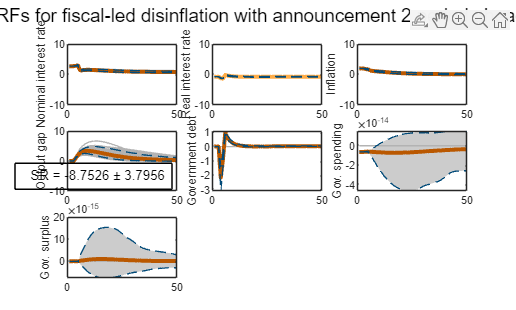

subplot(3,3,7)

fill([x, fliplr(x)], [s_5', fliplr(s_95')], [0.8, 0.8, 0.8], 'EdgeColor', 'none'); % Using a light grey color
hold on

% Plot each IRF in grey
for i_ = 1:100
    plot((y_non(SET.variable.s,:,i_)-y_non(SET.variable.s,:,i_))', 'Color', [0.7, 0.7, 0.7]) % Slightly darker grey than the shaded region
    hold on
end

% Plot the mean in red
plot(s_mean, 'Color', '#ba5800', 'LineWidth', 3)
hold on

% Plot the 95th and 5th percentiles in blue
plot(s_95, 'Color', '#024b79', 'LineWidth', 1, 'LineStyle', '--')
plot(s_5, 'Color', '#024b79', 'LineWidth', 1, 'LineStyle', '--')
hold on

ylabel('Gov. surplus')
graphTitle = sprintf('IRFs for fiscal-led disinflation with announcement %d period ahead', 6-4);
suptitle(graphTitle);
set(gcf, 'Position', [100, 100, 1000, 600]);
filename = sprintf('An%d_Fis.png', 2);
saveas(gcf, filename);
hold off